clear all;

Figures=true; %turn figures on and off

## Modeling of a custom Robot 

DH=[ %by Universal Robots (website)
   %a       alpha       d       theta
   0        pi/2        0.1519  0;
   -0.24365 0           0       0;
   -0.21325 0           0       0;
   0        pi/2        0.11235 0;
   0        -pi/2       0.08535 0;
   0        0           0.0819  0;
    ]

DH =          0    1.5708    0.1519         0
   -0.2437         0         0         0
   -0.2132         0         0         0
         0    1.5708    0.1124         0
         0   -1.5708    0.0853         0
         0         0    0.0819         0




ThetaOffset=DH(:,4); 

%get number of joints N 
[N,~,~]=size(DH); 

%create a ridid body tree Object 
myRobot=rigidBodyTree;

%create empty cell arrays for joint body and joints for N joints
bodies=cell(N,1);
joints=cell(N,1);



for i = 1:N

%number the bodies 
bodies{i}=rigidBody(['body' num2str(i)]);

%number the joints and define them as revolute or prismatic
joints{i}=rigidBodyJoint(['joint' num2str(i)], 'revolute');

%describe the Joint orientation based on corresponding DH parameters,
%define that we are using Denavit-Hartenberg parameters ('dh') 
%setFixedTransform() ignores the last entry (theta) as the angle is defined by the joint position 
setFixedTransform(joints{i},DH(i,:),'dh');

%connect body with joint
bodies{i}.Joint=joints{i};

%connect the links to create the robot 
if i==1 
    %First link is connected to the Base
    addBody(myRobot, bodies{i},'base');
else
    %following links are connected to the previous link
    addBody(myRobot, bodies{i},bodies{i-1}.Name);
end

%adding the offset
myRobot.Bodies{i}.Joint.HomePosition=DH(i,4);

end

%see the created robot 
showdetails(myRobot)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        body1        joint1      revolute             base(0)   body2(2)  
   2        body2        joint2      revolute            body1(1)   body3(3)  
   3        body3        joint3      revolute            body2(2)   body4(4)  
   4        body4        joint4      revolute            body3(3)   body5(5)  
   5        body5        joint5      revolute            body4(4)   body6(6)  
   6        body6        joint6      revolute            body5(5)   
--------------------


## Visualization

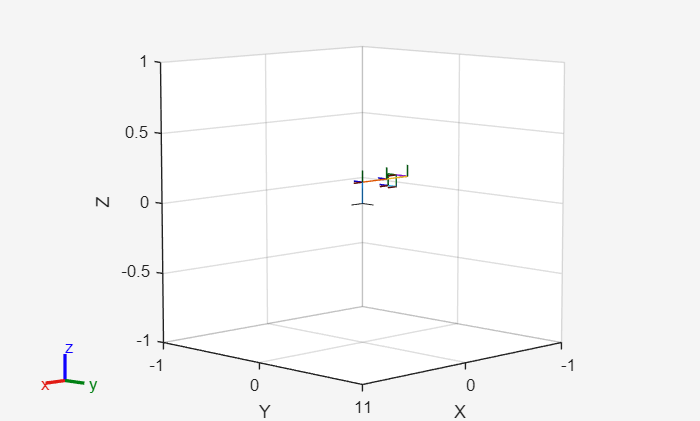

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



home=myRobot.homeConfiguration(); 


%visualize the robot at a specific configuration

figure(Name='myRobot home configuration'); 

if Figures
show(myRobot,home) 
end

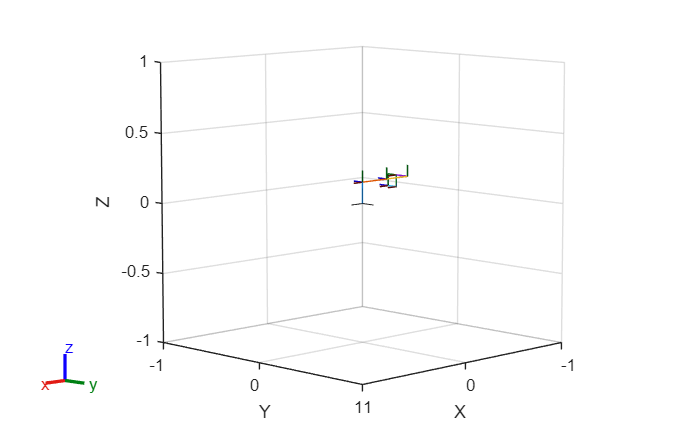

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%home is the default configuration
figure(Name='myRobot home configuration'); 
if Figures
show(myRobot) 
end

### Custom Configuration 

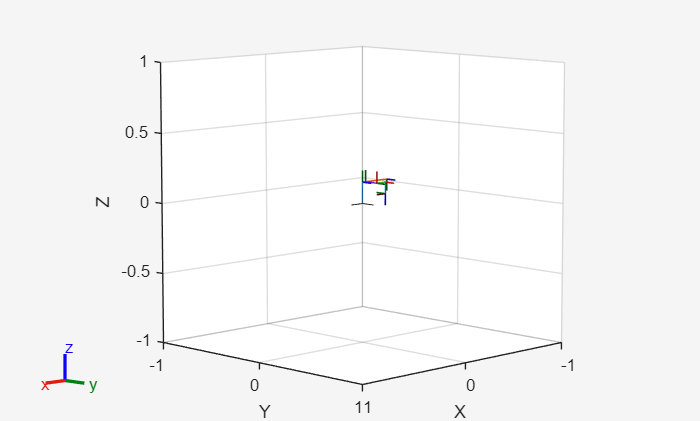

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%create a custom configuration, we start by copying the home configuration
%to keep the offsets
configA=myRobot.homeConfiguration(); 

%we can define our desired configuration
myconfig=[pi,pi,pi,pi/2,pi/2,pi/2];

%add the configuration to the Home configuration
for i=1:N
configA(i).JointPosition=configA(i).JointPosition+myconfig(i); 
end

figure(Name='myRobot configuration A'); 
if Figures
show(myRobot,configA) 
end

### Interactive visualization

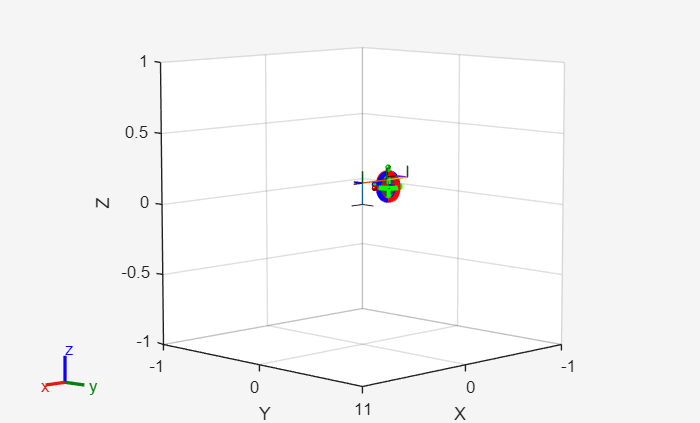

figure(Name="Interactive GUI - myRobot")
if Figures
mygui = interactiveRigidBodyTree(myRobot,MarkerScaleFactor=0.5);
end

### Loading existing models - UR3


figure(Name='UR3 Home configuration'); 
ur3=loadrobot("universalUR3")

ur3 =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'
    FrameNames: {'world'  'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}


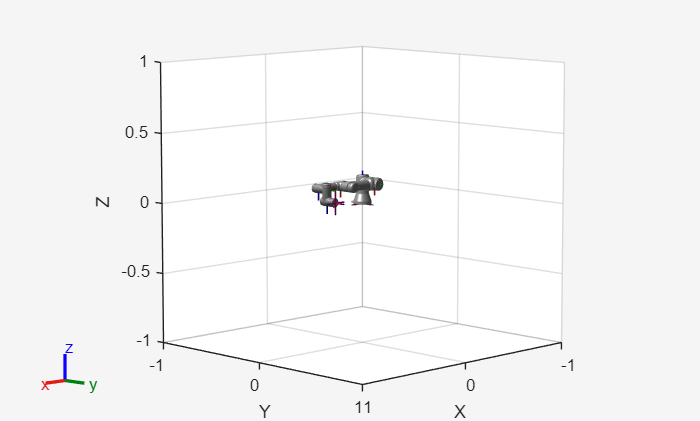

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ur3home=ur3.homeConfiguration();

% 
% for i=1:N
%     ur3home(i).JointPosition=myconfig(i);
% end

if Figures
show(ur3,ur3home)
end

### Interactive visualization UR3

figure(Name="Interactive GUI - UR3")

if Figures
ur3gui = interactiveRigidBodyTree(ur3,MarkerScaleFactor=0.5)
end

ur3gui =   interactiveRigidBodyTree with properties:

           RigidBodyTree: [1×1 rigidBodyTree]
                IKSolver: [1×1 generalizedInverseKinematics]
       SolverPoseWeights: [1 1]
             Constraints: {}
          MarkerBodyName: 'tool0'
     MarkerControlMethod: 'InverseKinematics'
       MarkerScaleFactor: 0.5000
              ShowMarker: 1
           Configuration: [6×1 double]
    StoredConfigurations: []
              MarkerPose: [4×4 double]
          MarkerBodyPose: [4×4 double]
